clear all

% Importar touchstones
PasaAltasConcentrado=sparameters('Touchstone files\ElementosDistribuidos\PasaAltasSParams.s2p')

PasaAltasConcentrado =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


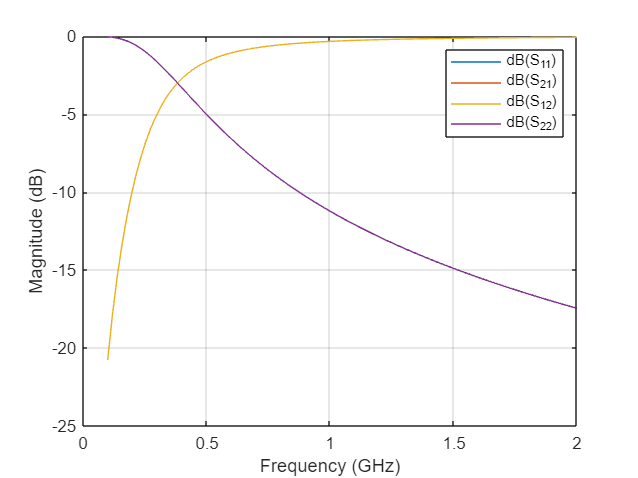

rfplot(PasaAltasConcentrado)


PasaAltasStubCapacitor=sparameters('Touchstone files\ElementosDistribuidos\StubPasaAltasSParams2.s2p')

PasaAltasStubCapacitor =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


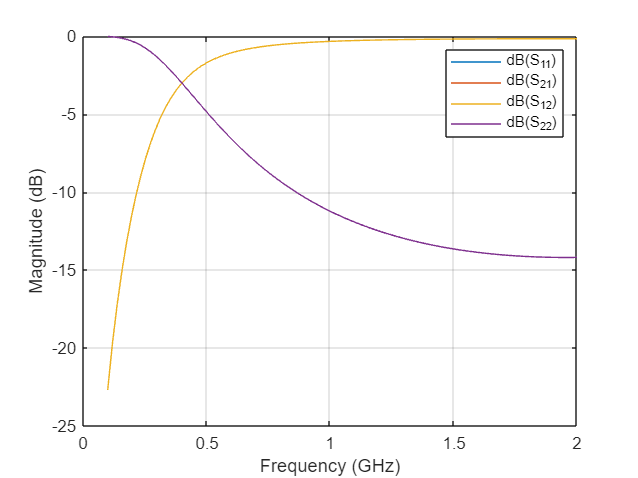

rfplot(PasaAltasStubCapacitor)


%Crear circuito con componentes concentrados

C1=capacitor(12E-12,'C1')

C1 =   capacitor: Capacitor element

    Capacitance: 1.2000e-11
           Name: 'C1'
      Terminals: {'p'  'n'}


L1=inductor(10E-9,'L1')

L1 =   inductor: Inductor element

    Inductance: 1.0000e-08
          Name: 'L1'
     Terminals: {'p'  'n'}


hckt=circuit('PasaAltas')

hckt =   circuit: Circuit element

    ElementNames: {}
           Nodes: []
            Name: 'PasaAltas'


add(hckt,[1 2],C1)
add(hckt,[2 0],L1)

setports(hckt,[1 0],[2 0])
freq=linspace(0.1E9,2E9,1000)

freq = 1.0e+09 *

    0.1000    0.1019    0.1038    0.1057    0.1076    0.1095    0.1114    0.1133    0.1152    0.1171    0.1190    0.1209    0.1228    0.1247    0.1266    0.1285    0.1304    0.1323    0.1342    0.1361    0.1380    0.1399    0.1418    0.1437    0.1456    0.1475    0.1494    0.1514    0.1533    0.1552    0.1571    0.1590    0.1609    0.1628    0.1647    0.1666    0.1685    0.1704    0.1723    0.1742    0.1761    0.1780    0.1799    0.1818    0.1837    0.1856    0.1875    0.1894    0.1913    0.1932


 S=sparameters(hckt,freq,50)

S =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [1000×1 double]
     Parameters: [2×2×1000 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


 % rfplot(S)

 %Crear circuito con componentes distribuidos
[txOut,nodes]=richards(C1,1E9,"StubMode","Shunt")

txOut =   txlineElectricalLength: ElectricalLength element

                  Name: 'C1_tx'
                    Z0: 13.2629
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Shunt'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}



nodes =

     []




L2=inductor(10E-9,'L2')

L2 =   inductor: Inductor element

    Inductance: 1.0000e-08
          Name: 'L2'
     Terminals: {'p'  'n'}


hckt2=circuit('PasaAltasLumped')

hckt2 =   circuit: Circuit element

    ElementNames: {}
           Nodes: []
            Name: 'PasaAltasLumped'


add(hckt2,[1 2],txOut)
add(hckt2,[2 0],L2)

setports(hckt2,[1 0],[2 0])
S_Lumped=sparameters(hckt2,freq,50)

S_Lumped =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [1000×1 double]
     Parameters: [2×2×1000 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


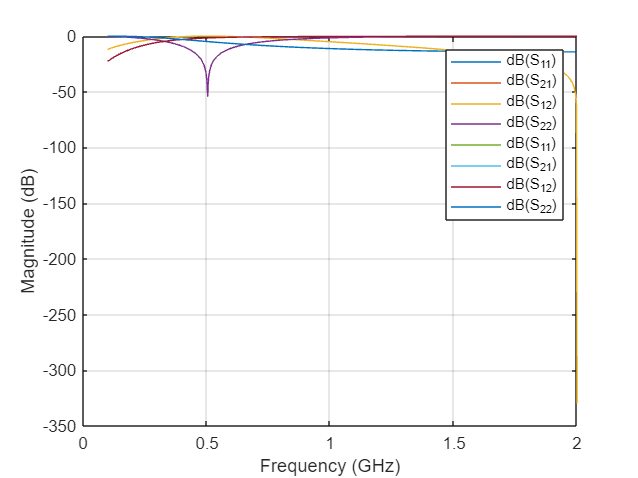


% Comparacion de graficas
rfplot(S_Lumped)  %Grafica creada del circuiot
hold on
rfplot(PasaAltasStubCapacitor)  % Grafica del touchstone